clear all
addpath('/Users/Ryo/Documents/GitHub/test-open/potential')
%%%39kV,3kV,0.6Ar,150
data_path="/Users/Ryo/mountpoint/210429"

data_path = "/Users/Ryo/mountpoint/210429"

time = 6

time = 7

time = 8

time = 9

time = 10

time = 11

time = 12

time = 13

time = 14

time = 15

time = 16

time = 17

time = 18

time = 19

time = 20

time = 21

time = 22

time = 23

time = 24

time = 25

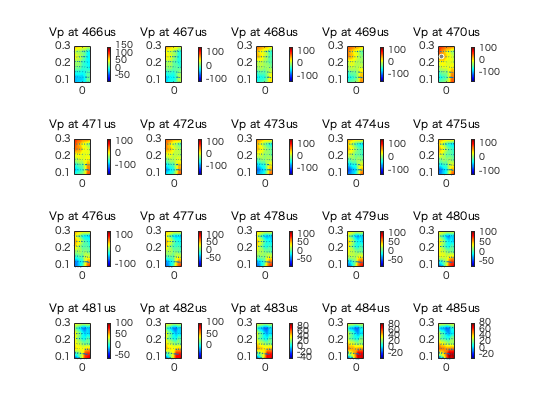

z=[0:20]*0.015-0.15;
R=[0:7]*0.03+0.1;
%mi=1.67E-27;%kg
mi=1.67E-27*39.95;
me=9.11E-31;%kg
Te=10.;%eV
offset=0.5*(log(mi/(2.*pi*me))-1.)*Te;
Vp_range=500.;
Bunatsu=1./50.;

shot=[1:15,34:37,39:42];
r_shot=[31,31,31,28,28,28,25,25,25,22,22,22,19,19,19,10,10,10,13,13,16,16,16];
C = unique(r_shot);
%filelist=data_path+'\ES_No'+shot+'.csv';
esdata=zeros(41,22,8) ;
for i = 1:8
    n= shot(r_shot==C(i));
    data=zeros(size(n,2),41,22); 
    for f=1:size(n,2)
     data(f,:,:)=import_ES(data_path+'/ES_No.'+n(f)+'.csv');
    end
    esdata(:,:,i)=mean(data);
end

esdata=esdata/Bunatsu+offset;

   for i=1:20
       time=i+5
       subplot(4,5,i)
       contourf(z,R,squeeze(esdata(time,2:22,:))',50,'LineStyle','none');
     colormap(jet)
        axis image
        axis tight manual
        %colorbar('Location','southoutside')
        colorbar('Location','eastoutside')
        hold on
        [pz,pr]=gradient(squeeze(esdata(time,2:22,:))',z,R);
        quiver(z,R,pz,pr)
        %axis equal
        hold off
        title('Vp at '+string(time+460)+'us')
        %ylim([-0.05 0.05])
        xlim([-0.05 0.05])
    end